## **Laboratorio 4 - Modelo Cinemátco Directo**

**Juan David Alonso**

**Julian Pinzón**

**Rodrigo Vera**

close all
clear all
%%Valores de DH


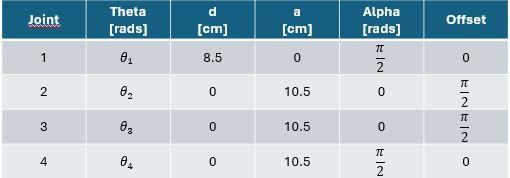


%%Matrices de tranformación homogenea
%Todos los angulos en radianes
%Todas las medidas en cm
syms Theta1 Theta2 Theta3 Theta4

T01 = DhtoMat(Theta1,8.5,0,pi/2)

$$T01 = \left(\begin{array}{cccc} \cos\left(\Theta_{1}\right) & 0 & \sin\left(\Theta_{1}\right) & 0\\ \sin\left(\Theta_{1}\right) & 0 & -\cos\left(\Theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{17}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = DhtoMat(Theta2+pi/2,0,10.5,0)

$$T12 = \left(\begin{array}{cccc} \cos\left(\Theta_{2}+\frac{\pi }{2}\right) & -\sin\left(\Theta_{2}+\frac{\pi }{2}\right) & 0 & \frac{21\,\cos\left(\Theta_{2}+\frac{\pi }{2}\right)}{2}\\ \sin\left(\Theta_{2}+\frac{\pi }{2}\right) & \cos\left(\Theta_{2}+\frac{\pi }{2}\right) & 0 & \frac{21\,\sin\left(\Theta_{2}+\frac{\pi }{2}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = DhtoMat(Theta3+pi/2,0,10.5,0) 

$$T23 = \left(\begin{array}{cccc} \cos\left(\Theta_{3}+\frac{\pi }{2}\right) & -\sin\left(\Theta_{3}+\frac{\pi }{2}\right) & 0 & \frac{21\,\cos\left(\Theta_{3}+\frac{\pi }{2}\right)}{2}\\ \sin\left(\Theta_{3}+\frac{\pi }{2}\right) & \cos\left(\Theta_{3}+\frac{\pi }{2}\right) & 0 & \frac{21\,\sin\left(\Theta_{3}+\frac{\pi }{2}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = DhtoMat(Theta4,0,6.5,pi/2)

$$T34 = \left(\begin{array}{cccc} \cos\left(\Theta_{4}\right) & 0 & \sin\left(\Theta_{4}\right) & \frac{13\,\cos\left(\Theta_{4}\right)}{2}\\ \sin\left(\Theta_{4}\right) & 0 & -\cos\left(\Theta_{4}\right) & \frac{13\,\sin\left(\Theta_{4}\right)}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T04 = T01*T12*T23*T34

%%Creación de los robots

%Posiciones requeridas en el desarrollo de la practica

R1 = [0 0 0 0 0];
R2 = [25 25 20 -20 0]*(pi/180);
R3 = [-35 35 -30 30 0]*(pi/180);
R4 = [85 -20 55 25 0]*(pi/180);
R5 = [80 -35 55 -45 0]*(pi/180);

%Matrices de rotación con las nuevas posiciónes
T04P1 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],R1(1:4)));
T04P2 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],R2(1:4)));
T04P3 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],R3(1:4)));
T04P4 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],R4(1:4)));
T04P5 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],R5(1:4)));

%Calculo de posiciónes
P1 = [T04P1(1:3,4);tr2eul(T04P1,'deg')'] %Posición 1

P1 =    -17
     0
    19
     0
     0
   180


P2 = [T04P2(1:3,4);tr2eul(T04P2,'deg')'] %Posición 2

P2 =   -16.0898
   -7.5028
    7.8446
 -155.0000
   25.0000
   -0.0000


P3 = [T04P3(1:3,4);tr2eul(T04P3,'deg')'] %Posición 3

P3 =   -17.8633
   12.5080
   12.4577
  145.0000
   35.0000
   -0.0000


P4 = [T04P4(1:3,4);tr2eul(T04P4,'deg')'] %Posición 4

P4 =    -0.7199
   -8.2285
    6.7151
  -95.0000
   60.0000
    0.0000


P5 = [T04P5(1:3,4);tr2eul(T04P5,'deg')'] %Posición 5

P5 =    -1.6905
   -9.5873
   16.2569
   80.0000
   25.0000
  180.0000


%% Serial link


L(1) = Link('revolute', 'alpha', pi/2,'a', 0 ,   'd', 8.5, 'offset', 0   , 'qlim', [-pi pi]);
L(2) = Link('revolute', 'alpha', 0,   'a', 10.5, 'd', 0  , 'offset', pi/2, 'qlim', [-pi pi]);
L(3) = Link('revolute', 'alpha', 0,   'a', 10.5, 'd', 0  , 'offset', pi/2, 'qlim', [-pi pi]);
L(4) = Link('revolute', 'alpha', pi/2,'a', 6.5,  'd', 0  , 'offset', 0   , 'qlim', [-pi pi]);

plot_options = {'workspace',[-60 60 -60 60 -30 60],'scale',.9};
Robot = SerialLink(L,'name','Robot','plotopt',plot_options)

 
Robot = 
 
Robot:: 4 axis, RRRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        8.5|          0|     1.5708|          0|
|  2|         q2|          0|       10.5|          0|     1.5708|
|  3|         q3|          0|       10.5|          0|     1.5708|
|  4|         q4|          0|        6.5|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


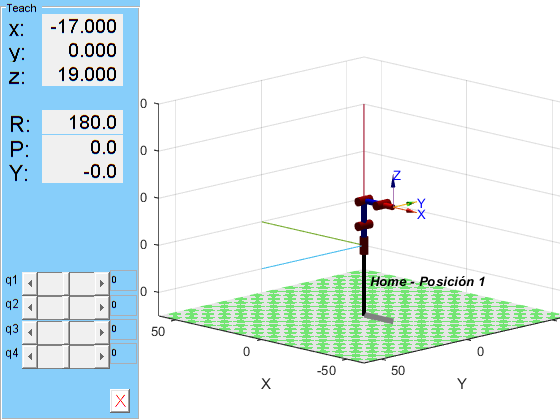

figure
Robot.name = 'Home - Posición 1';
Robot.teach(R1(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-15 15 5])

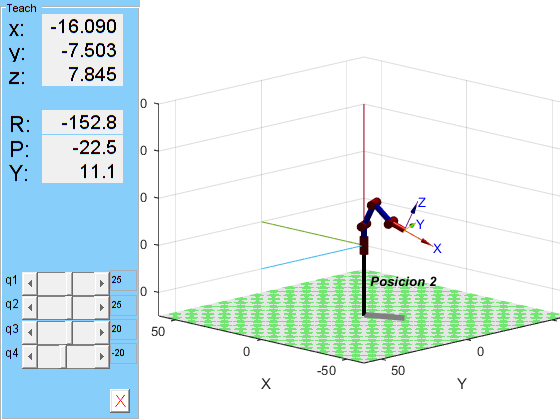

figure
Robot.name = 'Posicion 2';
Robot.teach(R2(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-15 15 5])

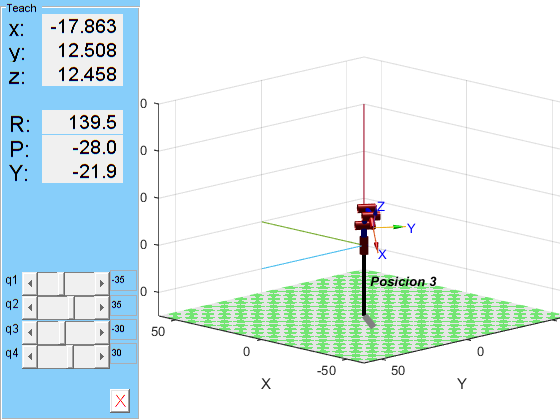

figure
Robot.name = 'Posicion 3';
Robot.teach(R3(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-15 15 5])

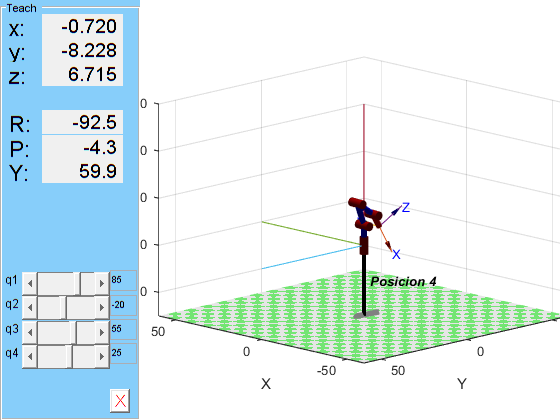

figure
Robot.name = 'Posicion 4';
Robot.teach(R4(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-15 15 5])

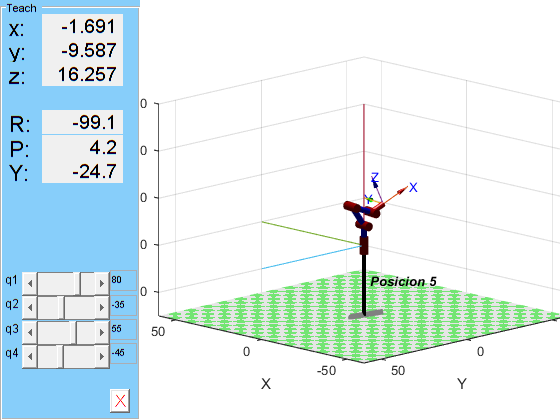

figure
Robot.name = 'Posicion 5';
Robot.teach(R5(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-15 15 5])

function MTH = DhtoMat(theta,d,a,alpha)
theta = rad2deg(theta);
alpha = rad2deg(alpha);
f1 = [cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta)];
f2 = [sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta)];
f3 = [0 sind(alpha) cosd(alpha) d];
f4 = [0 0 0 1];
MTH = [f1;f2;f3;f4];
end